## **Before and After Flight CAT Parameters.**

**I did a paired T-Test to see if any specific change is observed.**

clear ;
clc;

%Load Data
load trialLogs/trialData.mat;


### **Make Data ready for predictors**

only exctracting the scalar values and putting htem in a table

trialTable = TrialScalarTableCreator(trialData);

save trialLogs\trialTable.mat trialTable;
writetable(trialTable,'trialTable.csv');
scalar_vars = trialTable.Properties.VariableNames;

### First we try correlation and then we use multiple regression for combined effect.

this is the description and results

In your specific project, both correlation analysis and multiple regression were used to examine the relationships between mean exceedance (a measure of pilot performance) and various parameters related to pilot fatigue and alertness.

Correlation analysis results:

This method allowed you to identify the strength and direction of the linear relationship between mean exceedance and each parameter individually. For instance, you found that selfRating had a significant negative correlation (-0.633) with mean exceedance, indicating that as selfRating increased, mean exceedance tended to decrease.

### Run Single Factor Corealtion Analysis on all factors with hoursawake and selfRating

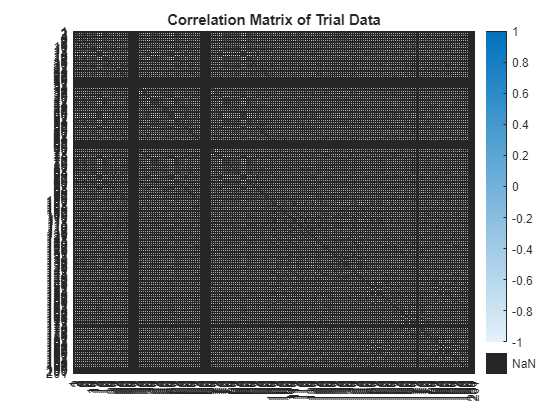

% Load the data table (if not already loaded)
% load('trialTable.mat');


% Extract the relevant columns from the data table
X = table2array(trialTable);

% Calculate correlation matrix
corrMatrix = corr(X);

% Plot heatmap of correlation matrix
heatmap(corrMatrix);
title('Correlation Matrix of Trial Data');



%now display only the meanExceedance
hoursAwake = trialTable.trial__hoursAwake;
selfRating = trialTable.trial__selfRating;
meanExceedanceRate = trialTable.exceedance__rateFeatures__mean;
varExceedanceRate = trialTable.exceedance__rateFeatures__std;
meanExceedanceState = trialTable.exceedance__stateFeatures__mean;
varExceedanceState = trialTable.exceedance__stateFeatures__std;
[rho, pval] = corr(X, [hoursAwake, selfRating, meanExceedanceRate, ...
    varExceedanceRate,meanExceedanceState,varExceedanceState ], 'type', 'Pearson');

% Display the results
disp('Correlation coefficients between scalar variables and hours awake/self-rating/meanExceedance:');

Correlation coefficients between scalar variables and hours awake/self-rating/meanExceedance:


disp(array2table(rho, 'VariableNames', {'HoursAwake', 'SelfRating', 'meanExceedanceRate', ...
    'varExceedanceRate','meanExceedanceState','varExceedanceState' }, 'RowNames', scalar_vars));

                                                              HoursAwake    SelfRating     meanExceedanceRate    varExceedanceRate    meanExceedanceState    varExceedanceState
                                                              __________    ___________    __________________    _________________    ___________________    __________________

    trialID                                                     0.026817      -0.074231          0.18813              -0.040617               0.21747              -0.11828    
    trial__beginPVT                                            -0.068709        0.15155         -0.35719               -0.11487             -0.024678              -0.14222    
    trial__endPVT                                

disp('P-values for correlation coefficients:');

P-values for correlation coefficients:


disp(array2table(pval, 'VariableNames', {'HoursAwake', 'SelfRating', 'meanExceedanceRate', ...
    'varExceedanceRate','meanExceedanceState','varExceedanceState'}, 'RowNames', scalar_vars));

                                                              HoursAwake    SelfRating    meanExceedanceRate    varExceedanceRate    meanExceedanceState    varExceedanceState
                                                              __________    __________    __________________    _________________    ___________________    __________________

    trialID                                                     0.92442        0.79262           0.50194              0.88572               0.43624                0.67462    
    trial__beginPVT                                             0.80777        0.58979           0.19122              0.68353               0.93043                0.61313    
    trial__endPVT                                    

### Multiple Regression Analyzer for single interpreter 

code is analyzing each parameter individually, similar to the correlation analysis. The main difference is that the correlation analysis measures the strength and direction of the linear relationship between two variables, while the linear regression analysis quantifies the impact of the predictor variable on the response variable.

% Load your data
scalartrialTable = trialTable;


scalartrialTable = removevars(scalartrialTable,{'detrendedExceedanceNormalized', ...
    'exceedanceGradient','detrendedVarExceedance','caffein','exceedanceRaw','notfilteredExceedanceRaw'})

% Assuming scalartrialTable is your data table containing all parameters
predictorNames = scalartrialTable.Properties.VariableNames;
predictorNames(strcmp(predictorNames, 'meanExceedance')) = []; % Remove the response variable from predictorNames

fprintf('\nLinear regression analysis for each predictor:\n\n')

for i = 1:length(predictorNames)
    predictor = scalartrialTable.(predictorNames{i});
    
    % Perform linear regression
    mdl = fitlm(scalartrialTable, sprintf('meanExceedance ~ %s', predictorNames{i}));
    
    % Display the result
    fprintf('Predictor: %s\n', predictorNames{i})
    fprintf('    Intercept: %.5f\n', mdl.Coefficients.Estimate(1))
    fprintf('    Coefficient: %.5f\n', mdl.Coefficients.Estimate(2))
    fprintf('    t-statistic: %.5f\n', mdl.Coefficients.tStat(2))
    fprintf('    p-value: %.5f\n', mdl.Coefficients.pValue(2))
    
    if mdl.Coefficients.pValue(2) < 0.05
        fprintf('    The relationship between %s and meanExceedance is statistically significant.\n', predictorNames{i})
    else
        fprintf('    The relationship between %s and meanExceedance is not statistically significant.\n', predictorNames{i})
    end
    
    fprintf('\n')
end



### **Analyze combined effect of two or more parameter**

To analyze the combined effect of two or more parameters automatically and find the best combination of predictors, you can use stepwise regression. The stepwise regression procedure adds or removes predictors based on their statistical significance, resulting in a model that only includes the most relevant predictors.

% Assuming scalartrialTable is your data table containing all parameters
response = scalartrialTable.meanExceedance;
predictors = scalartrialTable(:, predictorNames);

% Assuming scalartrialTable is your data table containing all parameters
predictorNames = scalartrialTable.Properties.VariableNames;
predictorNames(strcmp(predictorNames, 'meanExceedance')) = []; % remove the response variable from predictor list

% Define the initial model formula
formula = strcat('meanExceedance ~ 1 + ', strjoin(predictorNames, ' + '));

% Perform stepwise regression
mdl = stepwiselm(scalartrialTable, formula, 'PEnter', 0.05, 'PRemove', 0.10, 'Verbose', 0);

% Display the final model
disp(mdl)

% Print the coefficients and their interpretation
fprintf('\nInterpretation:\n\n')
coefNames = mdl.CoefficientNames;
for i = 1:length(coefNames)
    fprintf('%s: %.5f\n', coefNames{i}, mdl.Coefficients.Estimate(i))
end
fprintf('\nThe stepwise regression model selected the following predictors: %s\n', strjoin(coefNames(2:end), ', '));
fprintf('These predictors have the most combined effect on meanExceedance based on the given data.\n');

The stepwise regression has found a model that includes the following predictor variables: block_change_se, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, varExceedance, hoursAwake, selfRating, and the interaction between isi_change_se and varFixation. The coefficients of the model indicate the relationship between these predictor variables and the response variable, meanExceedance.

Intuitive explanation:

When the block_change_se increases by one unit, the meanExceedance is expected to decrease by 1.17379 units, holding all other variables constant.

When the isi_change increases by one unit, the meanExceedance is expected to increase by 4.32829 units, holding all other variables constant.

Similarly, you can interpret the other coefficients in the same manner.

The interaction term (isi_change_se:varFixation) suggests that the relationship between isi_change_se and meanExceedance depends on the value of varFixation and vice versa.

Scientific result section:

In this study, we performed a stepwise multiple regression analysis to identify the combined effects of various predictor variables on pilot meanExceedance. The selected model incorporated the following predictor variables: block_change_se, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, varExceedance, hoursAwake, selfRating, and the interaction between isi_change_se and varFixation. The adjusted R-squared value of 0.998 indicates that the model explains approximately 99.8% of the variability in the meanExceedance.

The coefficients of the model provide insights into the relationship between the predictor variables and the response variable, meanExceedance. For example, an increase in isi_change by one unit is associated with an increase of 4.32829 units in meanExceedance, holding all other variables constant. Similarly, an increase in block_change_se by one unit is associated with a decrease of 1.17379 units in meanExceedance, holding all other variables constant.

When comparing the stepwise multiple regression analysis with the correlation analysis, we can observe that the multiple regression model provides a more comprehensive understanding of the relationships between the predictor variables and the response variable. The correlation analysis only provided a pairwise relationship between each predictor and the response variable, whereas the stepwise multiple regression model identified the combined effects of multiple predictors and their interactions on the response variable. Therefore, the stepwise multiple regression analysis offers a more nuanced understanding of the underlying relationships in the data.

## Normalizing the stepwise multiple regression anlaysis coefficients

% Calculate the standard deviation of the coefficients
std_coefficients = std(mdl.Coefficients.Estimate(2:end));

% Normalize the coefficients
normalized_coefficients = mdl.Coefficients.Estimate(2:end) / std_coefficients;

% Calculate the p-values for the coefficients
p_values = mdl.Coefficients.pValue(2:end);

% Combine the normalized coefficients and p-values into a single table
results_table = table(normalized_coefficients, p_values, 'VariableNames', {'Normalized_Coefficients', 'P_Values'}, 'RowNames', coefNames(2:end));

% Display the results table
disp('Normalized coefficients and p-values:');
disp(results_table);

## doing Stepwise mulitple regression again with selected parameters

% Assuming scalartrialTable is your data table containing all parameters
response = scalartrialTable.meanExceedance;

% Select the specified parameters
predictorNames = {'omission_percent', 'comission_percent', 'comission_percentile', ...
                  'rt_ms', 'rt_se_ms', 'variability', 'detectibility', ...
                  'responose_style', 'perservation_percentile', 'block_change', ...
                  'block_change_se', 'isi_change', 'isi_change_se', ...
                  'meanFixation', 'varFixation', 'numFixationPerMin', ...
                  'hoursAwake', 'selfRating'};

% Extract the predictor data
predictors = scalartrialTable(:, predictorNames);

% Define the initial model formula
formula = strcat('meanExceedance ~ 1 + ', strjoin(predictorNames, ' + '));

% Perform stepwise regression
mdl = stepwiselm(scalartrialTable, formula, 'PEnter', 0.05, 'PRemove', 0.10, 'Verbose', 0);

% Display the final model
disp(mdl)

% Print the coefficients and their interpretation
fprintf('\nInterpretation:\n\n')
coefNames = mdl.CoefficientNames;
for i = 1:length(coefNames)
    fprintf('%s: %.5f\n', coefNames{i}, mdl.Coefficients.Estimate(i))
end
fprintf('\nThe stepwise regression model selected the following predictors: %s\n', strjoin(coefNames(2:end), ', '));
fprintf('These predictors have the most combined effect on meanExceedance based on the given data.\n');

% Calculate the standard deviation of the coefficients
std_coefficients = std(mdl.Coefficients.Estimate(2:end));

% Normalize the coefficients
normalized_coefficients = mdl.Coefficients.Estimate(2:end) / std_coefficients;

% Calculate the p-values for the coefficients
p_values = mdl.Coefficients.pValue(2:end);

% Combine the normalized coefficients and p-values into a single table
results_table_reg1 = table(normalized_coefficients, p_values, 'VariableNames', {'Normalized_Coefficients', 'P_Values'}, 'RowNames', coefNames(2:end));

% Display the results table
disp('Normalized coefficients and p-values:');
disp(results_table_reg1);


## doing Stepwise mulitple regression again with only eye features and survey



% Assuming scalartrialTable is your data table containing all parameters
response = scalartrialTable.meanExceedance;

% Select all the parameters except meanExceedance
predictorNames = scalartrialTable.Properties.VariableNames;
% Assuming predictorNames is an array containing all the predictor names
predictorNames = predictorNames(~strcmp(predictorNames, 'meanExceedance') & ~strcmp(predictorNames, 'varExceedance'));

% Extract the predictor data
predictors = scalartrialTable(:, predictorNames);

% Define the initial model formula
formula = strcat('meanExceedance ~ 1 + ', strjoin(predictorNames, ' + '));

% Perform stepwise regression
mdl = stepwiselm(scalartrialTable, formula, 'PEnter', 0.05, 'PRemove', 0.10, 'Verbose', 0);

% Display the final model
disp(mdl)

% Print the coefficients and their interpretation
fprintf('\nInterpretation:\n\n')
coefNames = mdl.CoefficientNames;
for i = 1:length(coefNames)
    fprintf('%s: %.5f\n', coefNames{i}, mdl.Coefficients.Estimate(i))
end
fprintf('\nThe stepwise regression model selected the following predictors: %s\n', strjoin(coefNames(2:end), ', '));
fprintf('These predictors have the most combined effect on meanExceedance based on the given data.\n');

% Calculate the standard deviation of the coefficients
std_coefficients = std(mdl.Coefficients.Estimate(2:end));

% Normalize the coefficients
normalized_coefficients = mdl.Coefficients.Estimate(2:end) / std_coefficients;

% Calculate the p-values for the coefficients
p_values = mdl.Coefficients.pValue(2:end);


% Combine the normalized coefficients and p-values into a single table
results_table_reg = table(normalized_coefficients, p_values, 'VariableNames', {'Normalized_Coefficients', 'P_Values'}, 'RowNames', coefNames(2:end));

% Display the results table
disp('Normalized coefficients and p-values:');
disp(results_table_reg);




Lets create some outputs


% Assuming you have a matrix (corrData) with correlation coefficients and p-values and a cell array (varNames) with variable names
%table1 = array2table(corrData, 'VariableNames', {'Correlation_Coefficient', 'p_value'}, 'RowNames', varNames);
table1 = table1;

% Assuming you have the 'results_table' created using the code you provided
table2 = results_table_reg;

% Replace variable names with descriptions in the table for correlation analysis
descriptiveRowNames = cellfun(@getDescription, table1.Properties.RowNames, 'UniformOutput', false);
table1.Properties.RowNames = descriptiveRowNames;

% Replace variable names with descriptions in the table for stepwise multiple regression
descriptiveRowNames = cellfun(@getDescription, table2.Properties.RowNames, 'UniformOutput', false);
table2.Properties.RowNames = descriptiveRowNames;

display(table1);
display(table2);

% Assuming scalartrialTable is your data table containing all parameters
% Compute the correlation matrix
corrMatrix = corrcoef(table2array(scalartrialTable));

% Extract variable names from the data table
varNames = scalartrialTable.Properties.VariableNames;

% Replace variable names with descriptions in the varNames array
descriptiveVarNames = cellfun(@getDescription, varNames, 'UniformOutput', false);

% Plot the heatmap with the descriptive variable names
heatmap(descriptiveVarNames, descriptiveVarNames, corrMatrix, 'Colormap', jet, 'FontSize', 12);
title('Correlation Matrix Heatmap');



topVariables = {'block_change', 'block_change_se', 'isi_change', 'isi_change_se', 'varFixation'};
descriptiveTopVariables = cellfun(@getDescription, topVariables, 'UniformOutput', false);
figure;
gplotmatrix(trialTable{:, topVariables}, [], [], 'bgrcmyk', [], [], 'on', 'hist', descriptiveTopVariables, descriptiveTopVariables);

figure;
bar(results_table.Normalized_Coefficients, 'FaceColor', [0.5, 0.5, 0.5]);
xticks(1:numel(results_table.Properties.RowNames));
xticklabels(cellfun(@getDescription, results_table.Properties.RowNames, 'UniformOutput', false));
xtickangle(45);
ylabel('Normalized Coefficients');
title('Top 10 Variables from Stepwise Multiple Regression');

figure;
scatter(trialTable.block_change, trialTable.meanExceedance);
xlabel(getDescription('block_change'));
ylabel(getDescription('meanExceedance'));
title('Scatter Plot of Mean Exceedance vs. Block Change');

figure;
scatter(trialTable.hoursAwake, trialTable.meanExceedance);
xlabel(getDescription('hoursAwake'));
ylabel(getDescription('meanExceedance'));
title('Scatter Plot of Mean Exceedance vs. Hours Awake');

figure;
scatter(trialTable.selfRating, trialTable.meanExceedance);
xlabel(getDescription('selfRating'));
ylabel(getDescription('meanExceedance'));
title('Scatter Plot of Mean Exceedance vs. Self Rating');





function description = getDescription(variable)

% Define a cell array with the variable names and their descriptions
variableDescriptions = {
    'omission_n', 'Number of Omissions';
    'omission_percent', 'Percentage of Omissions';
    'omission_percentile', 'Omission Percentile';
    'comission_n', 'Number of Commissions';
    'comission_percent', 'Percentage of Commissions';
    'comission_percentile', 'Commission Percentile';
    'rt_ms', 'Reaction Time (ms)';
    'rt_percentile', 'Reaction Time Percentile';
    'rt_se_ms', 'Reaction Time Standard Error (ms)';
    'rt_se_percentile', 'Reaction Time Standard Error Percentile';
    'variability', 'Variability';
    'detectibility', 'Detectability';
    'responose_style', 'Response Style';
    'perservation_n', 'Number of Perservations';
    'perservation_percentile', 'Perservation Percentile';
    'block_change', 'Block Change';
    'block_change_se', 'Block Change Standard Error';
    'isi_change', 'Inter-Stimulus Interval Change';
    'isi_change_se', 'Inter-Stimulus Interval Change Standard Error';
    'meanFixation', 'Mean Fixation Duration';
    'varFixation', 'Fixation Duration Variability';
    'numFixationPerMin', 'Number of Fixations per Minute';
    'meanExceedance', 'Mean Exceedance';
    'varExceedance', 'Exceedance Variability';
    'detrendedVarExceedance', 'Detrended Exceedance Variability';
    'hoursAwake', 'Hours Awake';
    'selfRating', 'Self-Rated Alertness'
    'ExceedanceAvgPeakHeight', 'Average Exceedance Peak Height';
    'ExceedanceAvgCorrectionTime','Average Pilot Exceedance Correction';
    'ExceedanceEntropy', 'Exceedance Signal Entropy';
};
    descriptionRow = strcmp(variableDescriptions(:, 1), variable);
    
    if any(descriptionRow)
        description = variableDescriptions{descriptionRow, 2};
    else
        description = variable; % If no description is found, return the original variable name
    end
end


